# International Travel Ban Effectiveness against viral outbreaks

**Sam Jackson and Smaran Vallabhaneni**

## The Question

*When do international travel bans need to go into effect in order to reduce the peak infection by 50%?*

**Explanation of question:**

In many scenarios, we have seen cases of viral outbreaks spread in exponential manners between countries, spreading which is further exasperated with an ever-increasingly connected world (Aghayan, S. K. et al.). With the start of the initial devastation of the COVID-19 pandemic, many countries have gone into self-isolation and international travel bans to prevent sick people from entering and sick people from leaving.

**Type of question:**

This is a direct, specific question asking about a certain aspect of travel and viral spread control, given certain conditions on the countries and people.

**Why is this question important:**

With several types of viral outbreaks becoming more and more common, and research showing that this is only expected to increase in the coming decades due to increased human-animal contact, urbanization, ever-increasing connectivity, immunity gaps, and climate change, it will soon become important on whether certain countries would benefit from regulating or outright banning international travel (Yang, B. et al). As seen in COVID-19, countries that managed to block travel early and do it properly have benefited the population more than a country who was unable to ban in time or uphold said ban. This can also help in policy and governmental planning between nations on how to handle future outbreaks.

**Research Synthesis Matrix:**

## The Model

### Methods and Model (Implementation)

This model is a hybrid of an agent-based simulation and the standard SIR model. For the purposes of this paper, we have five countries (or pods), and a total of 100 people. These 100 people, or agents, are split across the countries evenly, so in our case we have 20 agents per country. Each agent in this simulation has a home location defined by their pod and a unique ID (used by helper functions for tracking individuals). Depending on the given parameters and a seed, the agent will "travel" and relocate to another country. This travel process is done such that at the end of each simulation run there is still the same number of agents in each country, in this case 20. Then, a new connectivity graph is made and the SIR model is run on this graph. This process is repeated as many times as we want, in this case, 15 days.

**Parameters:**

*N_countries* - total countries (or pods)

*N_total* - total agents

*beta_per_edge* - the transmission probability between countries

*gamma* - recovery probability

*p_edge* - the transmission probability within a country

*avg_out_travel* - percent of agent who leave their country per day

*dt* - day step

*I0_idx* - initial infected agent

*n_runs* - helper variable, how many times to run to make average result

**Stock-and-Flow equations:**

S(t+1) = S(t) - (I(t) * S(t) * i)

I(t+1) = I(t) + (I(t) * S(t) * i) - (I(t) * r)

R(t+1) = R(t) + (I(t) * r)

As you can see, the stock and flow model is still the original, and this SIR is used on each agent. The only new part is the individual agentic running of this SIR model, done in the whole country-agent model.

**Tenchi diagram:**

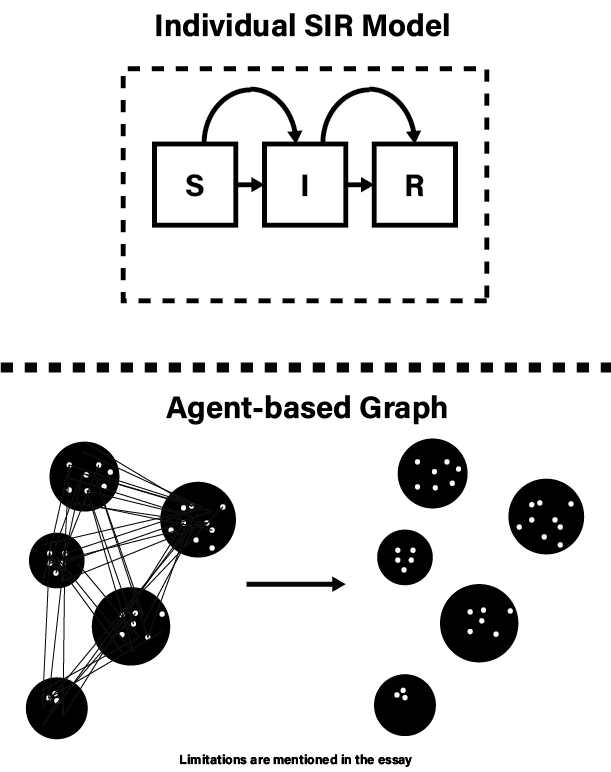

**Limitations:**

There are a couple of limitations to this model. One, this model does not take into account death, we assume everyone can recover. Two, this model assumes travel bans are one hundred percent effective. Three, we assume all countries have the exact same properties (note that country specifications were not modeled in the systems), so we cannot do international spread between different *types* of countries. Four, we assume everyone is the same in terms of health, so everyone largely gets affected and recovers in the same way (as dictated by the beta_per_edge, p_edge, and gamma variables). Five, this model does not take into account mutations or immuno-compromised people. Six, we assume all countries have the same population, for the purposes of keeping MATLAB happy. Seven, this model is run with a small population because of performance limitations on the host system. And, finally, eight, this model does not consider travel bans within a country - we just view a country as one 'room' or 'pod,' per se.

### Our Connection Graph

Although individuals migrate from pod to pod every timestep, our connectivity graph does not structurally change.  We will visualize it in matlab here.

country_population = 100;
number_of_countries = 5;
domestic_connection_weight = 100;
international_connection_weight = 0.001;


total_pop = country_population * number_of_countries;


function [con_mat] = make_con_mat(country_pop, country_num, dom_weight, int_weight)
    total_pop = country_pop * country_num;

    population_pattern = dom_weight * (ones(country_pop) - eye(country_pop));

    con_mat = ones(total_pop) * int_weight;

    for i = 0:(country_num - 1)
        offset = i * country_pop;
        con_mat(offset + (1:country_pop), offset + (1:country_pop)) = population_pattern;
    end
end

con_mat_wout_bans = make_con_mat(country_population, number_of_countries, domestic_connection_weight, international_connection_weight);

con_mat_w_bans = make_con_mat(country_population, number_of_countries, domestic_connection_weight, 0);

figure;

**Connectivity Graph Without Bans**

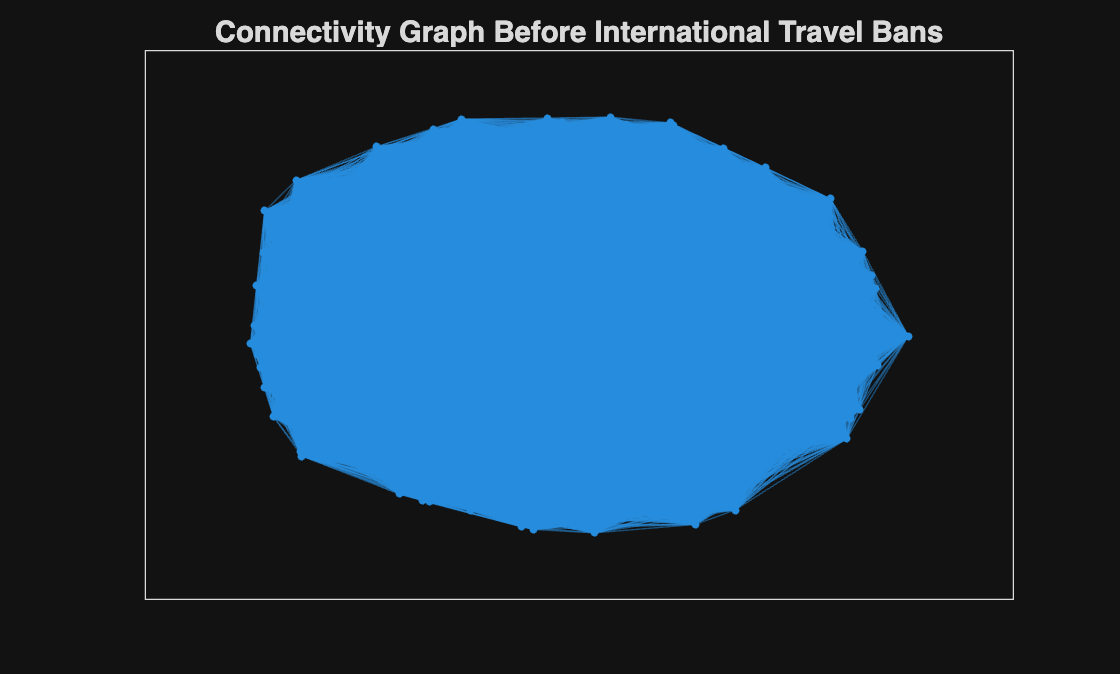

g = graph(con_mat_wout_bans);


plot(g, 'Layout', 'force');
title("Connectivity Graph Before International Travel Bans")

*Figure 1: Connectivity Graph Before Travel Bans*

**Connectivity Graph With Bans**

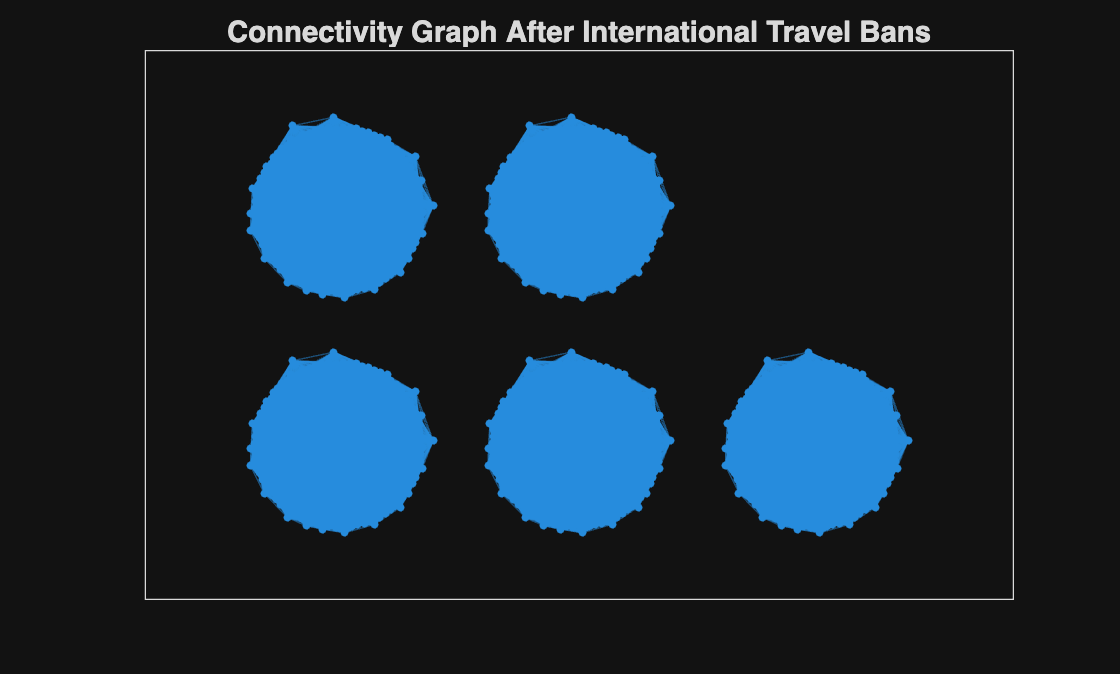

g = graph(con_mat_w_bans);

figure;
plot(g, 'Layout', 'force', 'WeightEffect', 'direct');
title("Connectivity Graph After International Travel Bans")

*Figure 2: Connectivity Graph After Travel Bans*

### Baseline Graph

Without a travel ban, this is how the simulation would run when averaged over 20 runs.

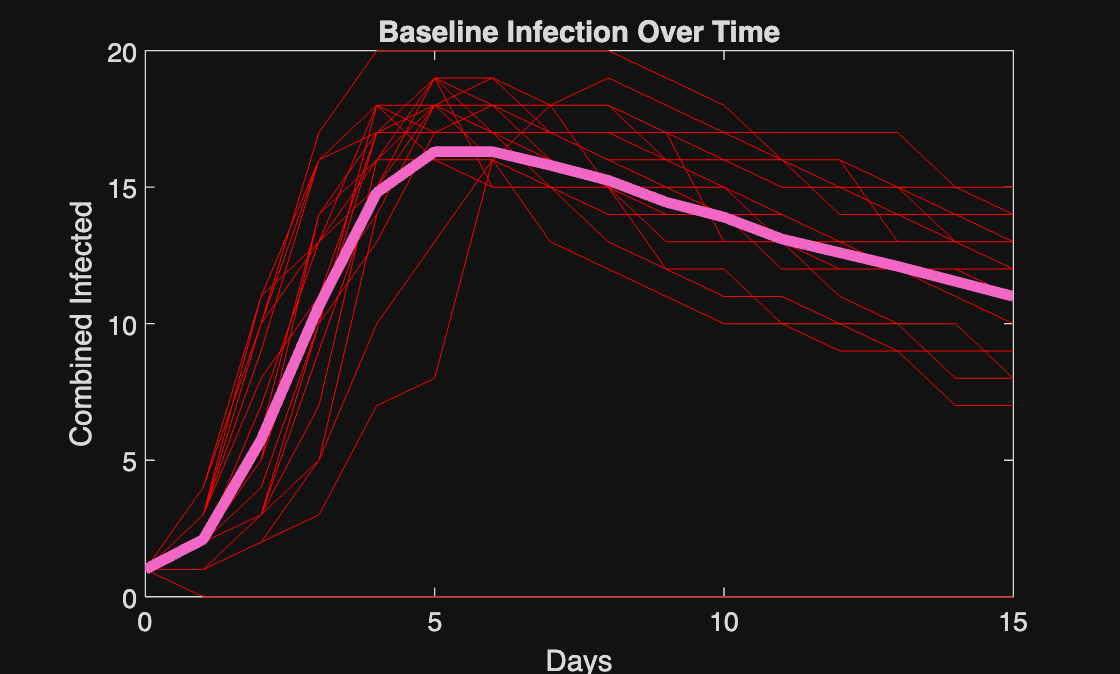

% Parameters
params.N_countries = 5;        % total countries (or 'pods')
params.N_total = 100;          % total agents
params.beta_per_edge = 0.7;    % transmission probability per contact per day
params.gamma = 0.05;           % recovery prob per day
params.p_edge = 0.7;           % prob edge exists in Erdos-Renyi contact graph within country
params.avg_out_travel = 0.7;   % fraction of persons leaving their country per day (row-sum of M)
params.t_max = 15;             % days
params.dt = 1;                 % day step (1)
params.I0_idx = 1;             % initial infected agent id index (or array)
params.n_runs = 20;            % stochastic repeats per ban time for averaging

% DO NOT TOUCH the following two vars
params.seed_mode = 'fixed';    % 'auto' or 'fixed' (if fixed will use run index to seed)
params.verbose = true;


% Distribute populations: equal by default
Nc = params.N_countries;
params.population = floor(params.N_total / Nc) * ones(Nc,1);
% if remainder, add 1 to first few countries
remn = params.N_total - sum(params.population);
params.population(1:remn) = params.population(1:remn) + 1;

% Build baseline travel matrix M (rows sum to avg_out_travel)
base_rate = params.avg_out_travel;
M = (base_rate/(Nc-1)) * (ones(Nc)-eye(Nc));
params.M = M;

% Ban sweep
ban_search.t_min = 0;
ban_search.t_max = 15;
ban_search.t_step = 1; % daily checks
ban_times = ban_search.t_min:ban_search.t_step:ban_search.t_max;

target_reduction = 50; % percent

% Generate static contact graphs & initial agent assignment
[agents_template, country_agent_ids, G_country] = init_agents_and_graphs(params);

% Baseline (no ban)
[peak_baseline_mean,peak_baseline_std, all_time_series, avg_days] = run_experiments_agent(params, agents_template, country_agent_ids, G_country, Inf);

all_days = zeros(length(avg_days), params.n_runs);
for i = 1:params.n_runs
    all_days(:, i) = all_time_series{i}.I_comb;
end

% Assertions:

% 

figure('Name','Baseline Infection Graph');

% Plot individual runs
plot(0:length(avg_days) -1, all_days, 'LineWidth', 0.1, 'LineStyle', '-', 'Color', '#FF0000'); hold on

% Plot baseline time series
plot(0:length(avg_days) -1, avg_days, 'LineWidth', 4);
xlabel('Days'); ylabel('Combined Infected');
title('Baseline Infection Over Time');

*Figure 3: Baseline infection graph across all countries, with no bans*

### Finding The Right Infection Time

Depending on when a travel ban is activated, how much is the peak infection reduced?

% Sweep ban times
n_b = numel(ban_times);
mean_peaks = zeros(n_b,1);
std_peaks  = zeros(n_b,1);

if params.verbose, disp('Sweeping ban times...'); end

Sweeping ban times...


for k = 1:n_b
    bt = ban_times(k);
    [mu, sigma, ~] = run_experiments_agent(params, agents_template, country_agent_ids, G_country, bt);
    mean_peaks(k) = mu;
    std_peaks(k) = sigma;
    if params.verbose
        fprintf('Ban at %2d d: mean peak = %.3f, std = %.3f\n', bt, mu, sigma);
    end
end

Ban at  0 d: mean peak = 19.850, std = 0.366
Ban at  1 d: mean peak = 4.200, std = 2.167
Ban at  2 d: mean peak = 7.850, std = 4.171
Ban at  3 d: mean peak = 12.000, std = 4.507
Ban at  4 d: mean peak = 15.900, std = 4.400
Ban at  5 d: mean peak = 16.950, std = 4.174
Ban at  6 d: mean peak = 17.350, std = 3.951
Ban at  7 d: mean peak = 17.350, std = 3.937
Ban at  8 d: mean peak = 17.400, std = 3.952
Ban at  9 d: mean peak = 17.400, std = 3.952
Ban at 10 d: mean peak = 17.400, std = 3.952
Ban at 11 d: mean peak = 17.400, std = 3.952
Ban at 12 d: mean peak = 17.400, std = 3.952
Ban at 13 d: mean peak = 17.400, std = 3.952
Ban at 14 d: mean peak = 17.400, std = 3.952
Ban at 15 d: mean peak = 17.400, std = 3.952


% compute percent reductions using mean peaks
reductions = 100 * (peak_baseline_mean - mean_peaks) / peak_baseline_mean;

% find earliest ban time achieving target reduction
idx = find(reductions >= target_reduction, 1, 'first');

if isempty(idx)
    fprintf('No ban time in [%d,%d] days reached >= %.1f%% mean peak reduction.\n', ban_search.t_min, ban_search.t_max, target_reduction);
else
    fprintf('Earliest ban day achieving >= %.1f%% mean peak reduction: %d days\n', target_reduction, ban_times(idx));
    fprintf('Mean peak then = %.3f (baseline = %.3f)\n', mean_peaks(idx), peak_baseline_mean);
end

Earliest ban day achieving >= 50.0% mean peak reduction: 1 days


Mean peak then = 4.200 (baseline = 17.400)


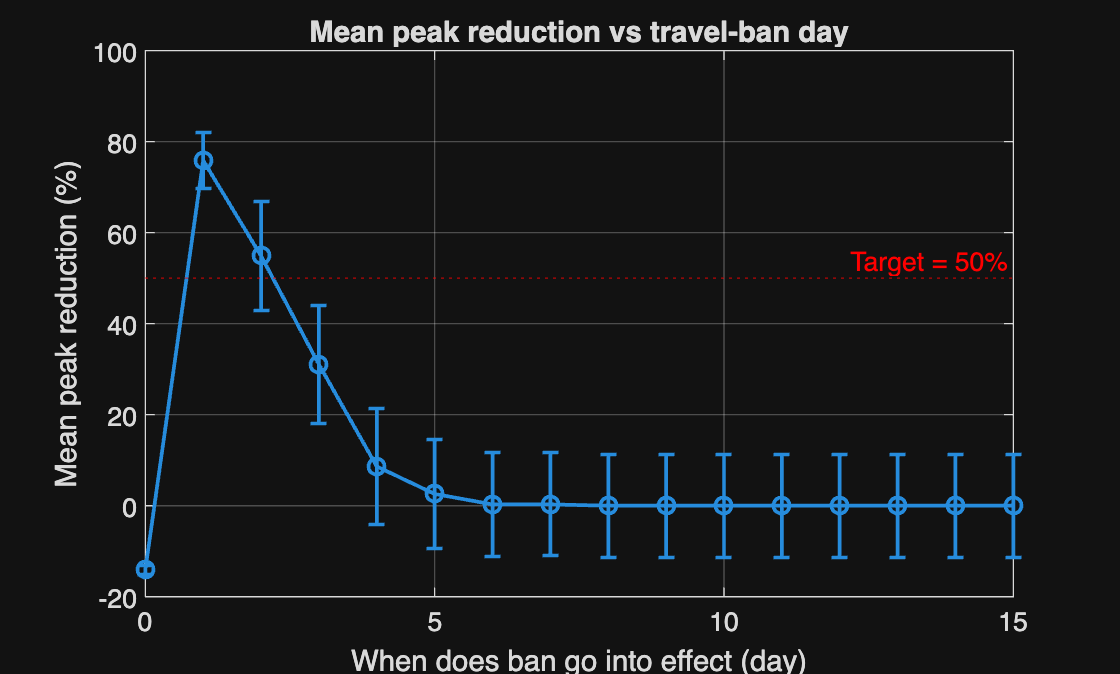

% Plot results: reduction vs ban time and baseline vs best
figure('Name','Peak reduction vs Ban time');
errorbar(ban_times, reductions, 0.5*std_peaks./peak_baseline_mean*100, '-o','LineWidth',1.4);
xlabel('When does ban go into effect (day)'); ylabel('Mean peak reduction (%)');
yline(target_reduction, ':r', sprintf('Target = %.0f%%', target_reduction));
title('Mean peak reduction vs travel-ban day');
grid on;

*Figure 4: Total Infection Peak Reduction (%) based on which day a travel ban is implemented*

Note that this graph is showing *when the ban goes into effect* on the x-axis, while the *mean peak reduction from the original baseline peak* is on the y-axis.

### The Results

From our graph above, we can see that, in order to decrease peak infection by at least 50%, a travel ban must go into effect at just **day one**. If we decide to apply said ban one day after finding out, we have the following graph, averaged out over 20 runs.

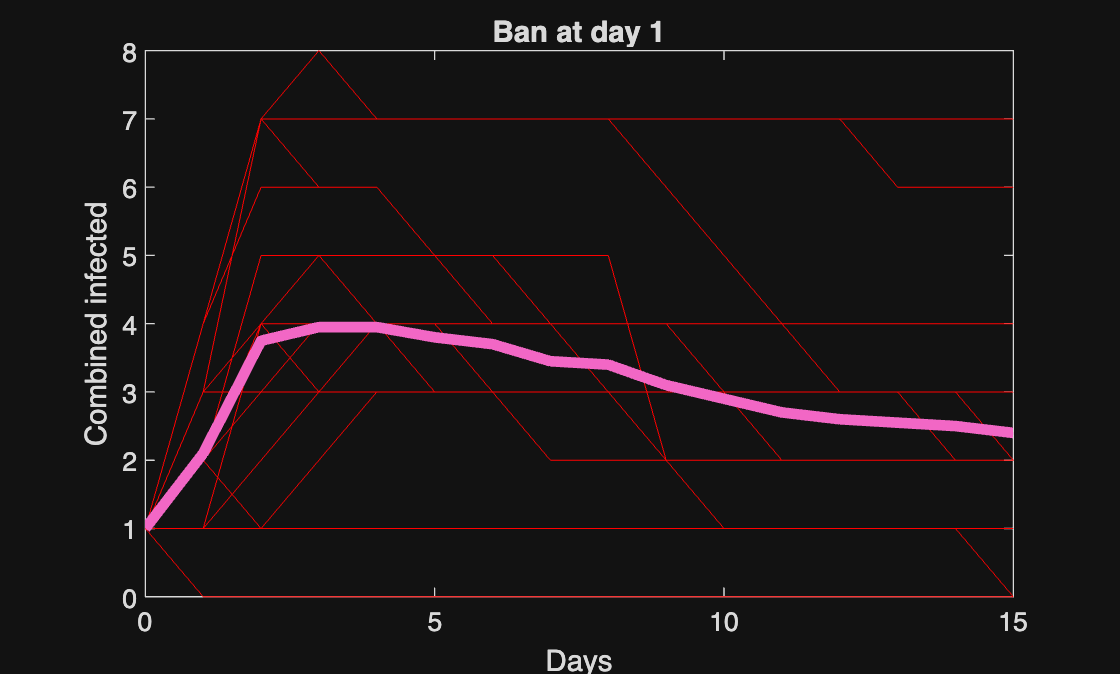

if ~isempty(idx)
    best_bt = ban_times(idx);
    
    [~, ~, all_ts, avg_days] = run_experiments_agent(params, agents_template, country_agent_ids, G_country, best_bt);

    all_days = zeros(length(avg_days), params.n_runs);
    for i = 1:params.n_runs
        all_days(:, i) = all_ts{i}.I_comb;
    end

    figure('Name','Combined infected (example runs)');

    % Plot individual runs
        plot(0:length(avg_days) -1, all_days, 'LineWidth', 0.1, 'LineStyle', '-', 'Color', '#FF0000'); hold on

    plot(0:length(avg_days) - 1, avg_days,'LineWidth',4); 
    xlabel('Days'); ylabel('Combined infected');
    
    title(sprintf('Ban at day %d', best_bt));
    %grid on;
end

*Figure 5: Infection graph with a ban instituted at the first day which causes at least a 50% peak reduction*

From here, we can see that the peak of the new graph works out to be under 50% of the original infection peak. We also see that in our total 20 runs, the simulation is quite a bit varied, with a min peak at one (the original) and a max peak of eight.

### **Verification**

To verify that our model is doing what we want it to, we placed assert() statements into our helper functions (below) to make sure that infections were not infecting themselves, the total population was not changing, and several other factors. We also examined our infection graphs to make sure that there were no strange behaviors and they matched what we expected.

### Conceptual Validation

The effectiveness of travel bans at curbing infection and decreasing infection peak can be seen in the real world. During the COVID-19 pandemic, South Korea delayed enacting its travel restrictions in comparison to surrounding countries, and ended up with a higher number of cases (Gwee, S. X. W. et al.).

## The Interpretation

Our results show that enacting a travel ban after just one day of the viral infection of the population is infected is enough to decrease the peak infection by 50% in an international scenario. This supports the claim that travel bans are an effective way to curb pandemics. However, they have to work almost perfectly. According to the NIH, "Substantial evidence suggests the need of a near complete shutdown of global travel to contain the epidemic modestly" (Gwee, S. X. W. et al.). It is widely agreed that the COVID-19 pandemic could have been contained and largely prevented weeks after it was discovered with a global 100% travel ban, but such a ban is not feasible.

Now, while it does make sense that the earlier we place the ban the earlier we stop the infection, it must be mentioned that this model simply assumes bans between countries. If on just day one the infected person has managed to infect another country, that is a potential of fourty people getting sick. Furthermore, there is the question on whether the infected person actually moves at all, and if not, then their own country is still susceptible to him, as stated in the limitations.

In conclusion, travel bans can be very effective when they are strictly enforced, as we have shown with our model, but in reality they should be combined with other infection prevention techniques, and not exclusively relied upon.

## AI Disclosure

We used google gemini to find sources, which we then read and cited.  We did not use any AI tools in our code development or essay writing.

## The Sources

Gwee, S. X. W., Chua, P. E. Y., Wang, M. X., & Pang, J. (2021). Impact of travel ban implementation on COVID-19 spread in Singapore, Taiwan, Hong Kong and South Korea during the early phase of the pandemic: a comparative study. *BMC infectious diseases*, *21*(1), 799. [https://doi.org/10.1186/s12879-021-06449-1](https://doi.org/10.1186/s12879-021-06449-1)

Aghayan, S. K., Moghadas Hosseinzadeh, F., Department of Veterinary Medicine, Shabestar Branch, Islamic Azad University, Shabestar, Iran, & Department of Microbiology, Faculty of Medicine, Tehran Medical Sciences, Islamic Azad University, Tehran, Iran. (2025). The impact of traveling on infectious diseases transmission with a focus on air travel: A Narrative Review. In *Int J Travel Med Glob Health* (Vols. 1–41) [Journal-article]. [https://doi.org/10.30491/ijtmgh.2024.485399.1439](https://doi.org/10.30491/ijtmgh.2024.485399.1439)

Yang, B., Sullivan, S. G., Du, Z., Tsang, T. K., & Cowling, B. J. (2022). Effectiveness of International Travel Controls for Delaying Local Outbreaks of COVID-19. *Emerging infectious diseases*, *28*(1), 251–253. [https://doi.org/10.3201/eid2801.211944](https://doi.org/10.3201/eid2801.211944)